# Analysing Domains Samples Using Custom Layers Models.

For custom models, all the work with calculating the reflectivity from the different domains is done within the custom model itself. 

To do this, there is an additional input into the custom model file which denotes the domain to be calculated...

The final 'domain' input is always either 1 or 2, denoting which domain is being calculated. Then, within the custom model, we can calculate the layers structure for whichever domain structure is required in this pass through the function...

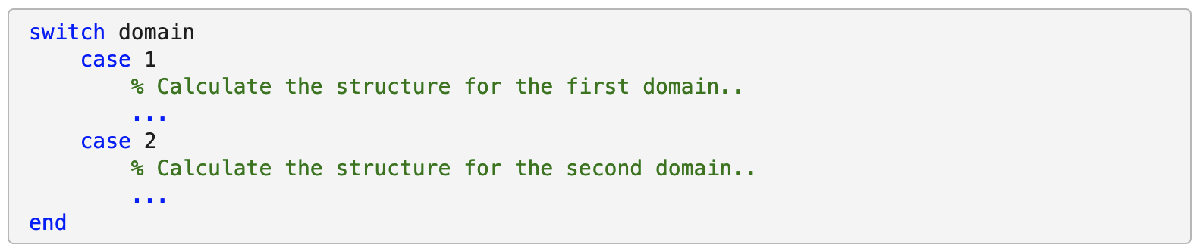

We will make a simple example of a permalloy layer on silicon, which has spin up and spin down domains, each with different SLD's...

                                                           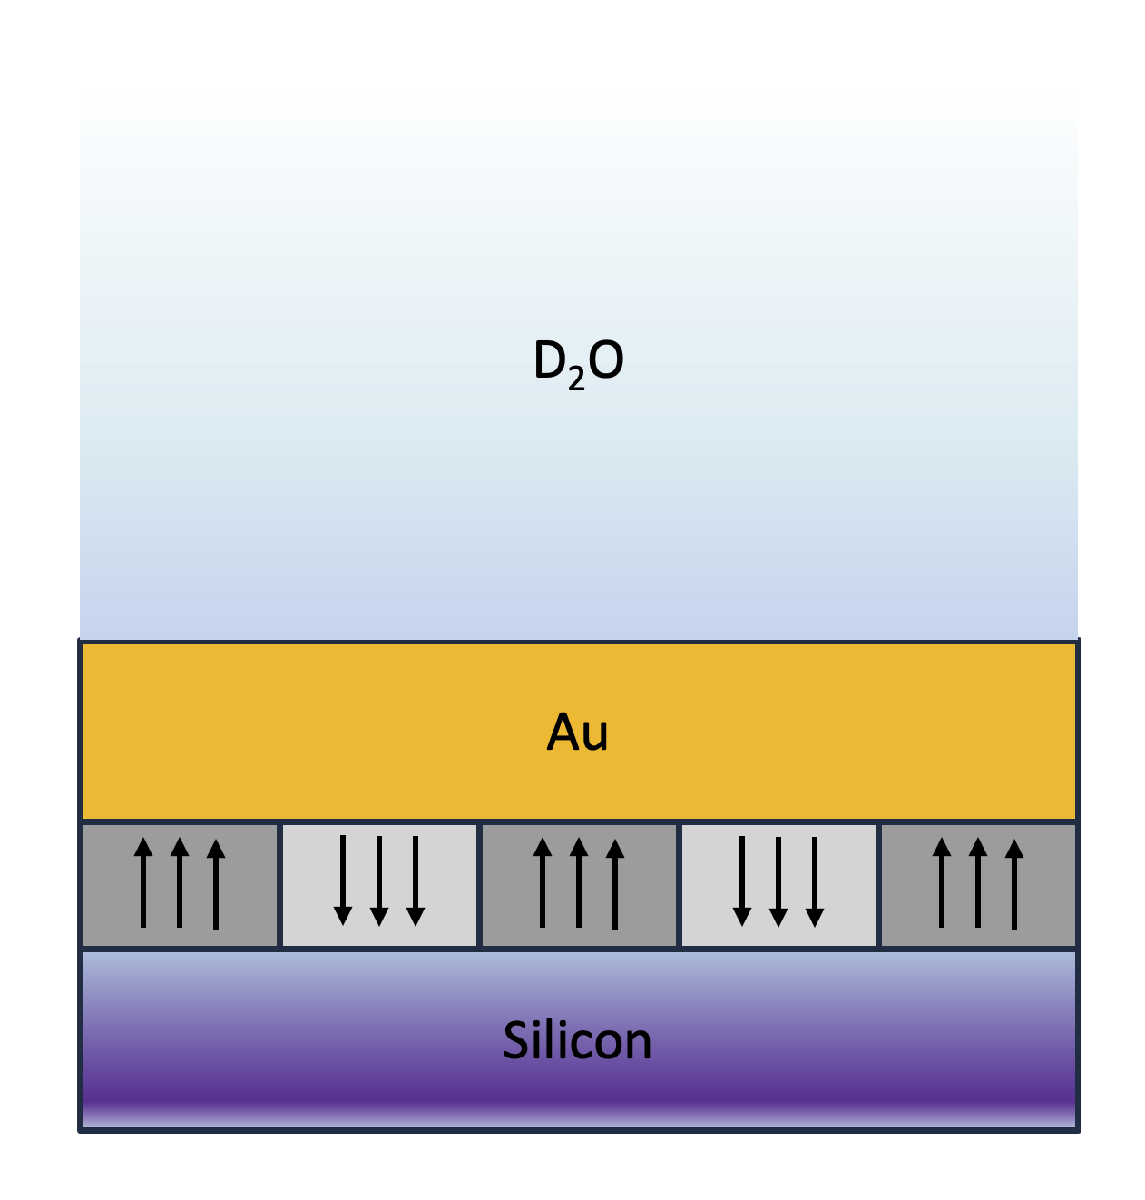

We start by setting up the project....

% Test of custom layers domains prioject...
% Use incoherent summing on a permalloy layer
% as a test

problem = createProject(calcType="domains");
problem.setModelType('custom layers');
problem.setGeometry('substrate/liquid');

% Make some parameters...
params = {{'Alloy thick',   100,    150,    200,   true}
          {'Alloy SLD up',  9e-6,   11e-6,  13e-6, true}
          {'Alloy SLD dn',  5e-6,   7e-6,   10e-6, true}
          {'Alloy rough',   5,      7,      11,    true}
          {'Gold thick',    100,    150,    200,   true}
          {'Gold SLD',      4e-6,   4.5e-6, 5e-6,  true}
          {'Gold Rough',    5,      7,      11,    true}};

problem.addParameterGroup(params);

% Set the bulk SLD
problem.setBulkIn(1,'name','Silicon','Value',2.073e-6,'max',2.073e-6);

% Add the custom file...
problem.addCustomFile('Alloy domains', 'alloyDomains.m', 'matlab', pwd);

% Make a contrast...
problem.addContrast('name',        'D2O Conrast', ...
                    'Data',        'Simulation',...
                    'Background',  'Background 1',...
                    'BulkIn',      'Silicon',...
                    'BulkOut',     'SLD D2O',...
                    'Scalefactor', 'Scalefactor 1', ...
                    'Resolution',  'Resolution 1',...
                    'Resample',     false,...
                    'domainRatio', 'Domain Ratio 1');

problem.setContrastModel(1,'Alloy domains');

disp(problem)

In the project, we are using a custom function which we have called 'alloyDomains'...

type alloyDomains.m

Note that the main difference between this and a 'normal' custom function is the extra 'domain' input, which we then use to select which domain we compute using the 'switch / case' instruction at the end of the function

To run this, we make a controls block as usual, and send it to RAT....

controls = controlsClass();
[problem,results] = RAT(problem,controls);

plotRefSLD(problem,results)